% DEMO_FOURDOF_LOBPCG
%   Runs the 4-DOF LOBPCG example and prints diagnostics.

clear; clc;

problem = 2; %1 = 4DOF spring, 2 =) 1000DOF Spring, 3 = testingEIFEM matrices

solver = Testing_LOBPCG(problem);

% Optional knobs:
solver.b      = 4;        % number of modes
solver.use_precond = true;
solver.use_physical_x = true; % feed aproximation to eigenvaluees (simulating coarse from superelement) as starting point
 solver.tol    = 1e-6;    % residual tolerance
 solver.maxit  = 1000;       % max iterations
 solver.verbose = false;

results = solver.run_demo();

Elapsed time is 0.000600 seconds.


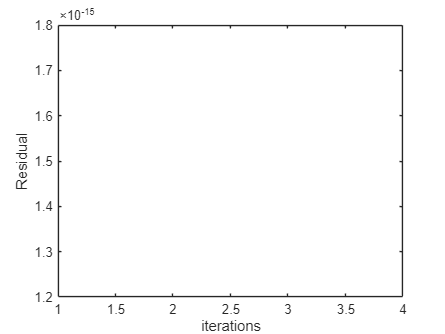


x_axis = 1:length(results.history.rnorms);
plot(x_axis,results.history.rnorms(:,1),x_axis,results.history.rnorms(:,2),x_axis,results.history.rnorms(:,3))
xlabel('iterations')
ylabel('Residual')